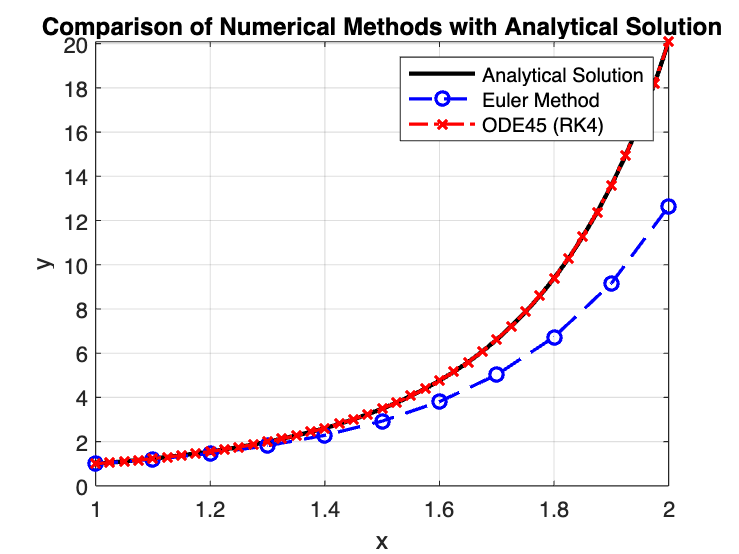

% Define the differential equation
f = @(x, y) 2*x*y;

% Initial condition and interval
x0 = 1;
y0 = 1;
xf = 2; % Define the final value of x
N = 10; % Number of steps for Euler's method
h = (xf - x0) / N; % Step size

% Euler's method
xe = x0:h:xf;
ye = zeros(1, length(xe));
ye(1) = y0;
for i = 1:length(xe)-1
    ye(i+1) = ye(i) + h*f(xe(i), ye(i));
end

% RK4 method
[xr, yr] = ode45(f, [x0 xf], y0);

% Analytical solution
xa = linspace(x0, xf, 100);
ya = exp(xa.^2 - 1);

% Plot
figure;
plot(xa, ya, 'k-', 'LineWidth', 2); hold on;
plot(xe, ye, 'b--o', 'LineWidth', 1.5);
plot(xr, yr, 'r-.x', 'LineWidth', 1.5);
legend('Analytical Solution', 'Euler Method', 'ODE45 (RK4)');
title('Comparison of Numerical Methods with Analytical Solution');
xlabel('x');
ylabel('y');
grid on;